Problem 1:

We'll start by creating our random background distribution. We can use Matlab's poissfit function to calculate the mean of our random poisson distribution - and indeed it is very close to 100. We can use this to plot the pdf, and to calculate the values corresponding to the statistical threshold of 5 sigma. Because the poissinv function calculates the inverse of the cdf, 1 - 5sigmaprobability will return the upper threshold, and the inverse of 5sigmaprobability will return the lower 5 sigma threshold. Like always, the probability corresponding to 5 sigma is 2.866e-7. 

x = poissrnd(100,[1,100000])

x =     93   104    96    85   101    92   115   103   106    99   106   103   102    88   124    78   100    85   105   100    96   108   118   114    99    95    98    94   120   100   100   118   101    96   109   108    83   102    93    76   100   112    98    95   100   103   107    99    99   113


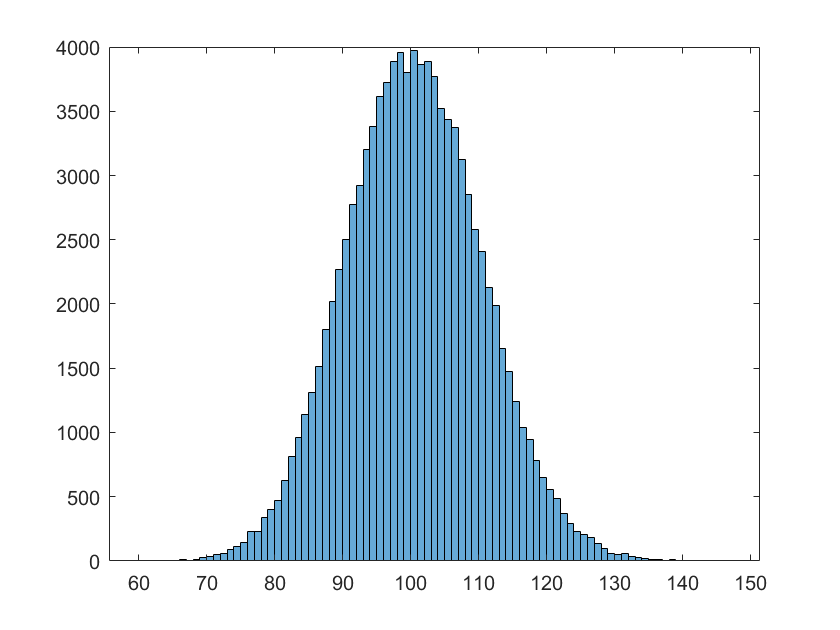

v =   Histogram with properties:

             Data: [1×100000 double]
           Values: [1×87 double]
          NumBins: 87
         BinEdges: [1×88 double]
         BinWidth: 1
        BinLimits: [60 147]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


v = histogram(x)

mean = poissfit(x)

mean = 100.0279

y = 50:150

y =     50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99


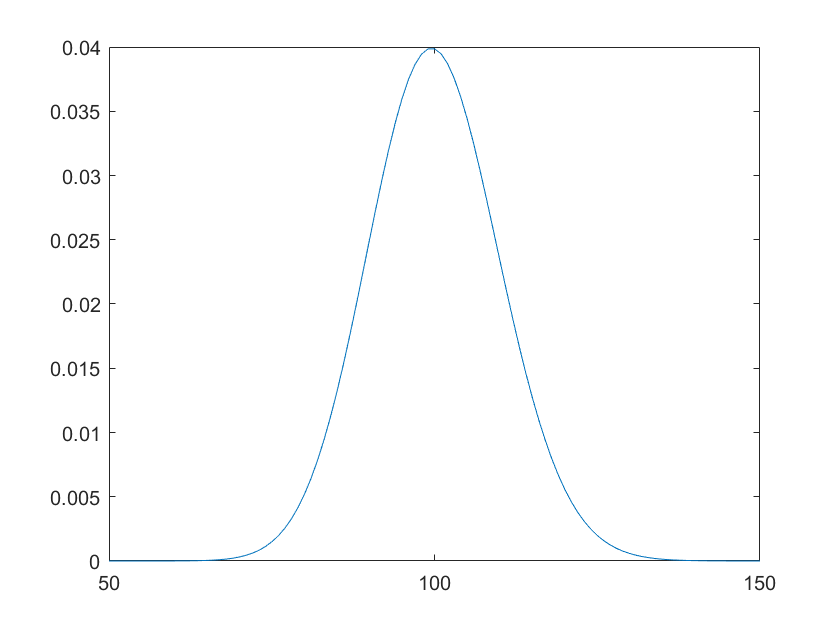

plot(y,poisspdf(y,mean),"Linewidth",0.2)

thresh = poissinv(1-2.866e-7,mean)

thresh = 154

thres2 = poissinv(2.866e-7,mean)

thres2 = 54

Problem 2: 

First we'll need to calculate what probability would correspond to a 8sigma signal. Sigma probabilities are calculated from a Normal distribution with a mean of 0 and standard deviation of 1. This allows us to calculate the 8sigma probability from the cdf of our Gaussian distribution. 

eightsigmaprobability = normcdf(8,0,1,'upper')

eightsigmaprobability = 6.2210e-16

esp = eightsigmaprobability

esp = 6.2210e-16

eightsigmavalue = poissinv(1-esp,mean)

eightsigmavalue = 190

lowereightsigmavalue = poissinv(esp,mean)

lowereightsigmavalue = 31

Now that we have our 8sigma value, we can inject this signal on top of our background. Our 8 sigma value is 190, and the mean of our distribution is roughly 100. In order to generate values in our dataset around 190, we'll have to add 190. We'll also collect all the values of our signal data in a separate data set. 

x1 = x;
x2 = zeros([1,5000])

x2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


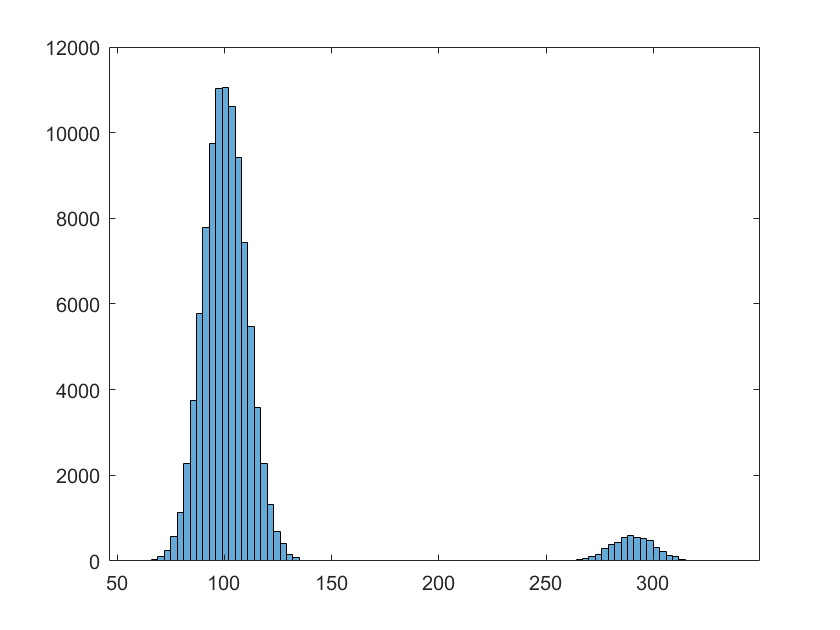

for k = 1:5000
    x1(1,5.*k) = x1(1,5.*k) + 190;
    x2(1,k) = x1(1,5.*k);
end
figure
histogram(x1)

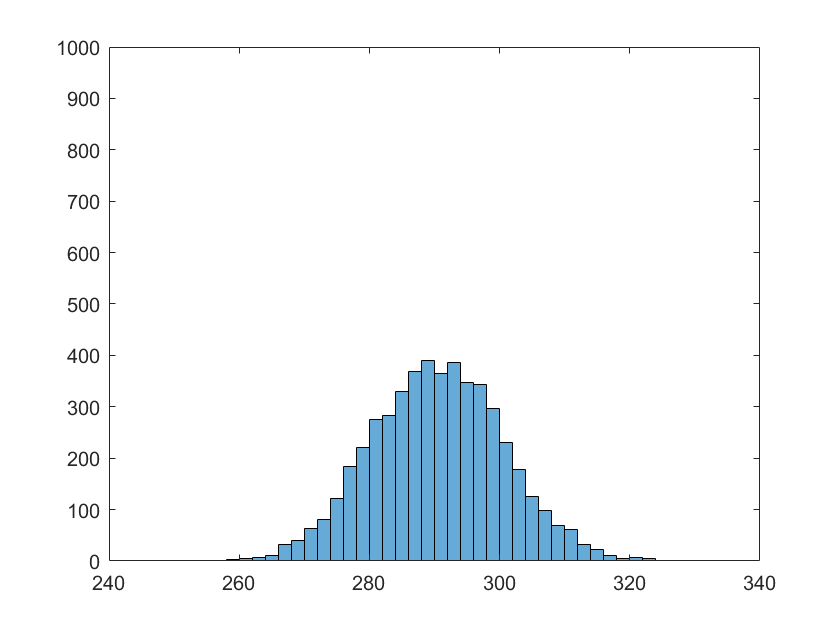


histogram(x2)
xlim([240,340])
ylim([0,1000])


l = poissfit(x2);
l1 = 250:330;
figure
plot(l1,poisspdf(l1,l),"Linewidth",0.1)
hold on
test = histogram(x2,"Normalization",'pdf')

test =   Histogram with properties:

             Data: [1×5000 double]
           Values: [1×40 double]
          NumBins: 40
         BinEdges: [256 258 260 262 264 266 268 270 272 274 276 278 280 282 284 286 288 290 292 294 296 298 300 302 304 306 308 310 312 314 316 318 320 322 324 326 328 330 332 334 336]
         BinWidth: 2
        BinLimits: [256 336]
    Normalization: 'pdf'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


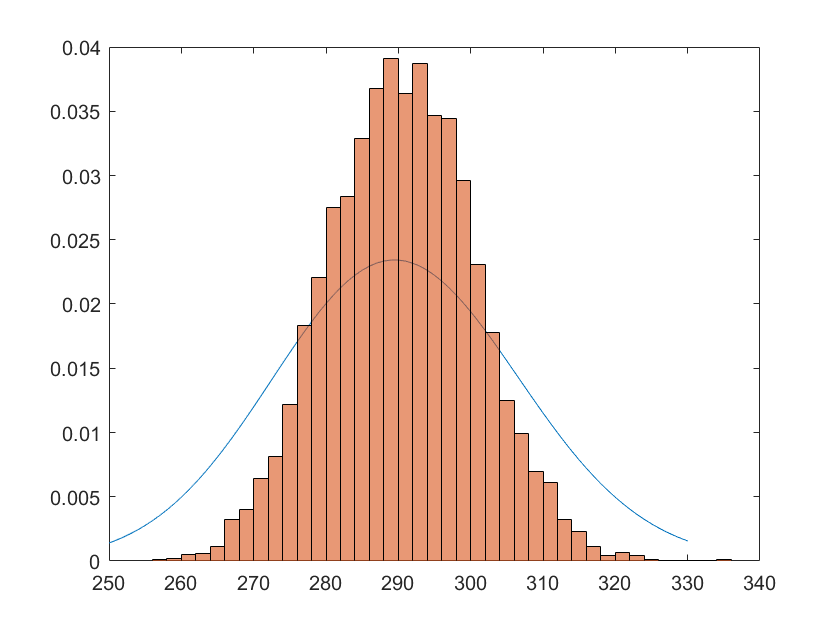

hold off

Our pdf doesn't quite appear to be Poisson - this isn't too surprising, given it should have the shape of a Poisson distribution centered at 100, but displaced 90 to the right, so a pdf of a Poisson distribution centered at 190 shouldn't perfectly match. Let's try a Gaussian fit. 

[a,b] = normfit(x2)

a = 289.9758

b = 10.0847

figure
plot(l1,normpdf(l1,a,b),"Linewidth",0.5)
hold on
test = histogram(x2,"Normalization",'pdf')

test =   Histogram with properties:

             Data: [1×5000 double]
           Values: [1×40 double]
          NumBins: 40
         BinEdges: [256 258 260 262 264 266 268 270 272 274 276 278 280 282 284 286 288 290 292 294 296 298 300 302 304 306 308 310 312 314 316 318 320 322 324 326 328 330 332 334 336]
         BinWidth: 2
        BinLimits: [256 336]
    Normalization: 'pdf'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


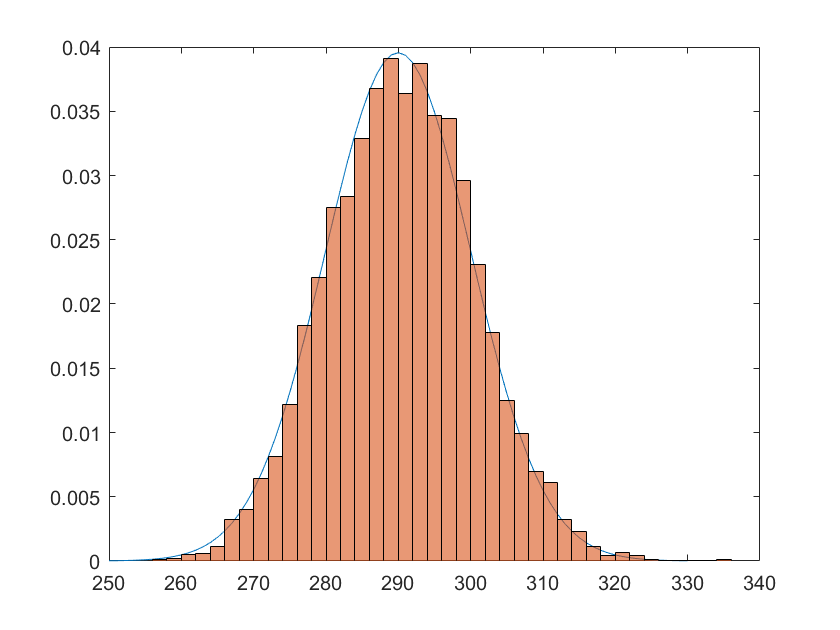

hold off

figure
plot(l1,normpdf(l1,a,b),"Linewidth",0.5)
set(gca,'Yscale','Log')
hold on
test = histogram(x2,"Normalization",'pdf')

test =   Histogram with properties:

             Data: [1×5000 double]
           Values: [1×40 double]
          NumBins: 40
         BinEdges: [256 258 260 262 264 266 268 270 272 274 276 278 280 282 284 286 288 290 292 294 296 298 300 302 304 306 308 310 312 314 316 318 320 322 324 326 328 330 332 334 336]
         BinWidth: 2
        BinLimits: [256 336]
    Normalization: 'pdf'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


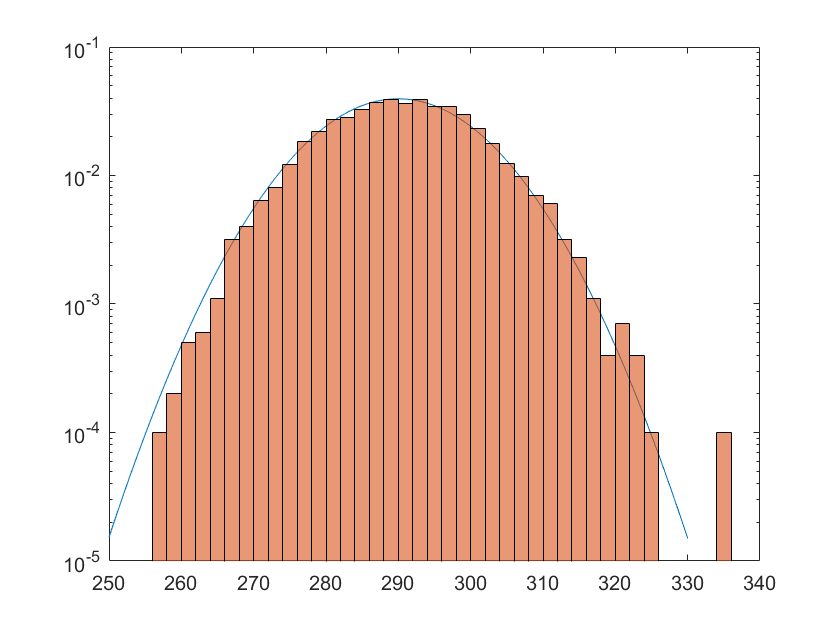

hold off

This Gaussian fit works much better than our Poisson fit - this is also not surprising, since we could have probably made a good Gaussian fit to our original data. Therefore the displacement of our Poisson distribution centered at 100, displaced 90, can also have a Gaussian fit to it. 

Let's test whether our signal is biased one way or the other, by integrating our pdf above and below 190 and then subtracting both sides. Then we'll double check the integral of the signal pdf above and below 190 is 0.5. 

test = normcdf(290,a,b,'upper') - normcdf(290,a,b)

test = -0.0019

test1 = normcdf(290,a,b,'upper')

test1 = 0.4990

test2 = normcdf(290,a,b)

test2 = 0.5010

We can see that our observed signal shows very little bias above or below our true injected signal. 

Problem 3: 

We'll repeat our process from problem 2 with different injected signal values ranging in 10 step intervals from 0 to 260. 

x1 = x;
x2 = zeros([1,700])

x2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for k = 1:50
    x1(1,k) = x1(1,k) + 100 - mean;
    x2(1,k) = x1(1,k);
end
for k = 51:100
    x1(1,k) = x1(1,k) + 110 - mean;
    x2(1,k) = x1(1,k);
end
for k = 101:150
    x1(1,k) = x1(1,k) + 120 - mean;
    x2(1,k) = x1(1,k);
end
for k = 151:200
    x1(1,k) = x1(1,k) + 130 - mean;
    x2(1,k) = x1(1,k);
end
for k = 201:250
    x1(1,k) = x1(1,k) + 140 - mean;
    x2(1,k) = x1(1,k);
end
for k = 251:300
    x1(1,k) = x1(1,k) + 150 - mean;
    x2(1,k) = x1(1,k);
end
for k = 301:350
    x1(1,k) = x1(1,k) + 160 - mean;
    x2(1,k) = x1(1,k);
end
for k = 351:400
    x1(1,k) = x1(1,k) + 170 - mean;
    x2(1,k) = x1(1,k);
end
for k = 401:450
    x1(1,k) = x1(1,k) + 180 - mean;
    x2(1,k) = x1(1,k);
end
for k = 451:500
    x1(1,k) = x1(1,k) + 190 - mean;
    x2(1,k) = x1(1,k);
end
for k = 501:550
    x1(1,k) = x1(1,k) + 200 - mean;
    x2(1,k) = x1(1,k);
end
for k = 551:600
    x1(1,k) = x1(1,k) + 220 - mean;
    x2(1,k) = x1(1,k);
end
for k = 601:650
    x1(1,k) = x1(1,k) + 240 - mean;
    x2(1,k) = x1(1,k);
end
for k = 651:700
    x1(1,k) = x1(1,k) + 260 - mean;
    x2(1,k) = x1(1,k);
end
x3 = x1(1,1:700)

x3 =    92.9721  103.9721   95.9721   84.9721  100.9721   91.9721  114.9721  102.9721  105.9721   98.9721  105.9721  102.9721  101.9721   87.9721  123.9721   77.9721   99.9721   84.9721  104.9721   99.9721   95.9721  107.9721  117.9721  113.9721   98.9721   94.9721   97.9721   93.9721  119.9721   99.9721   99.9721  117.9721  100.9721   95.9721  108.9721  107.9721   82.9721  101.9721   92.9721   75.9721   99.9721  111.9721   97.9721   94.9721   99.9721  102.9721  106.9721   98.9721   98.9721  112.9721


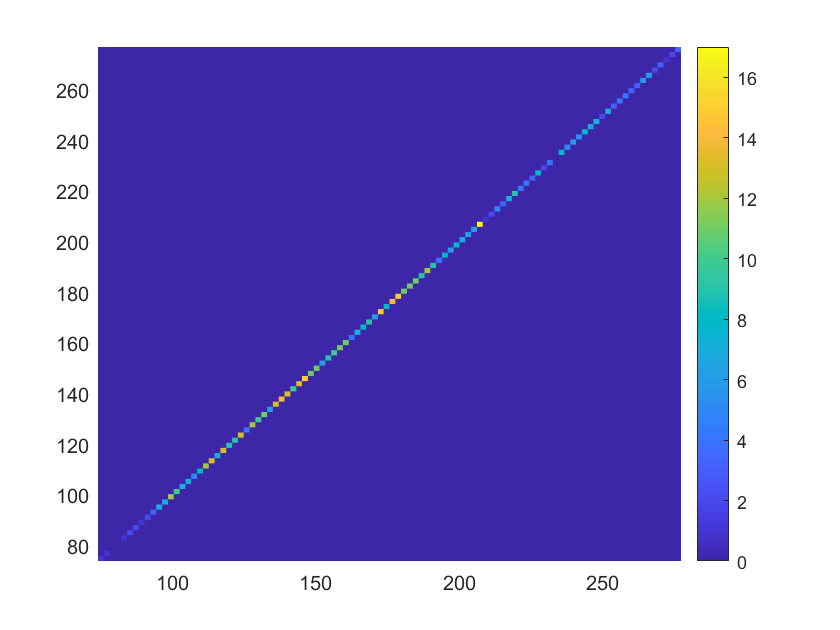

histogram2(x2,x3,100,"DisplayStyle","tile",'ShowEmptyBins','on')
colorbar


x1  = x(1,1:1001);
signalstrength = linspace(0,1000,1001)

signalstrength =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


[scratch, signal] = meshgrid(signalstrength)

scratch =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49
     0     1     2     3     4     5     6     7     8     9    10    11    12    13   

signal =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3     3     3     3     3    

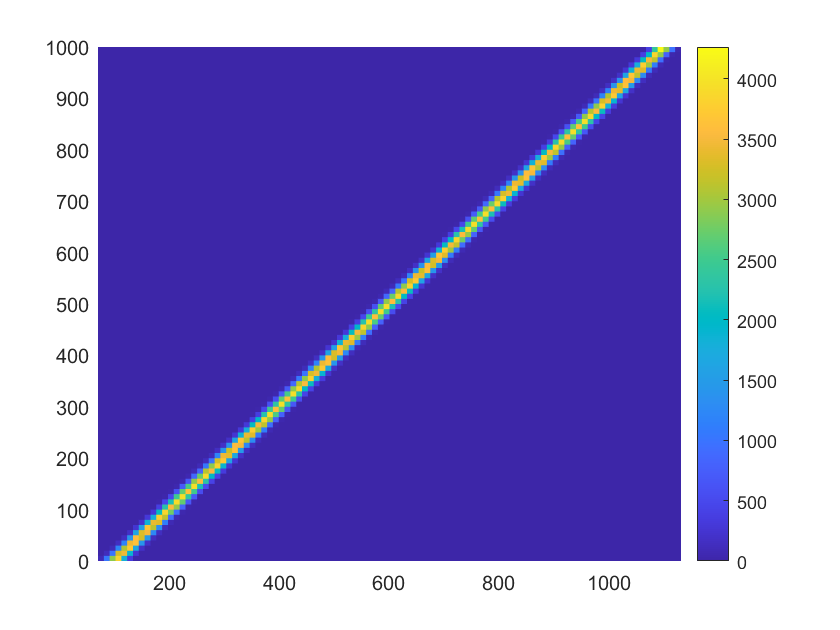

obs = x1 + signal;

histogram2(obs,signal,100,"DisplayStyle","tile",'ShowEmptyBins','on')
colorbar